# Treating all data

clear; close; clc;
load('sandro_all.mat');

Plotting some PVT and KSS data

figure(1)
scatter(datetime(pvtApp.datetime),pvtApp.velAvgSlowest,'LineWidth',1.4); hold on;
scatter(datetime(pvtApp.datetime),pvtApp.velAvg,'LineWidth',1.4);
legend([{'Slowest'},{'Avg.'}]); hold off;

Read the data from the KSS/PVT App.

aux = pvtApp.velAvg;

time = datetime(pvtApp.datetime);
days = day(time); hours = hour(time); minutes = minute(time);

dt.tr = 24*(days - min(days)) + hours + minutes/60;

j = 1; k = 1;
for i = 1 : length(days)
    index = 1 + (days(i)-min(days));
    dt.t{index,1}(k,1) = dt.tr(j);
    dt.y{index,1}(k,1) = aux(j);
    j = j + 1;
    k = k + 1;
    if (i>1) && (i<length(aux))
        if days(i)~=days(i+1)
            k =1 ;
        end
    end
    dt.init(index) = dt.t{index}(1);
    dt.final(index) = dt.t{index}(end);
end

Ploting the data figures

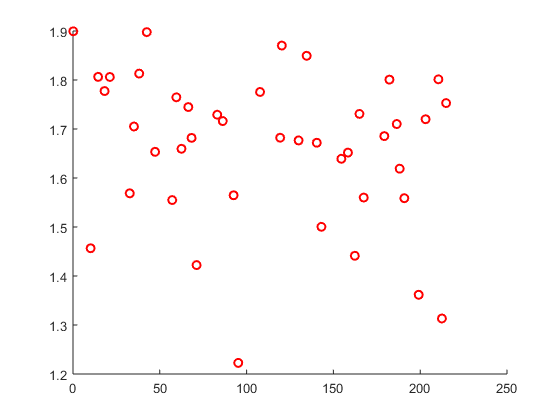

figure(2)
scatter(cell2mat(dt.t),cell2mat(dt.y),'r','LineWidth',1.5); hold off;

Eliminating days 4 and 5:

% k = 1;
% for j = 1 : length(dt.y)
%     if (j~=5) && (j > 5)
%         dte.y{k,1} = dt.y{j};
%         dte.t{k,1} = dt.t{j} -(dt.t{6}(1) - dt.t{5}(1));
%         dte.init(k) = dt.init(j) - (dt.t{6}(1) - dt.t{5}(1));
%         dte.final(k) = dt.final(j) - (dt.t{6}(1) - dt.t{5}(1));
%         k = k + 1;
%     elseif (j~=5) && (j < 5)
%         dte.y{k,1} = dt.y{j};
%         dte.t{k,1} = dt.t{j};
%         dte.init(k) = dt.init(j);
%         dte.final(k) = dt.final(j);
%         k = k + 1;
%     end
% end
% 
% figure(3)
% scatter(cell2mat(dte.t),cell2mat(dte.y),'r','LineWidth',1.5); hold off;

# Estimate the model

Use the functions to estimate both the model and the structure for a particular person

  Curiosity point - 1


  Curiosity point - 2


  Curiosity point - 3


  Curiosity point - 4


  Curiosity point - 5


  Curiosity point - 6


  Curiosity point - 7


  Curiosity point - 8


  Curiosity point - 9


  Curiosity point - 10


  Curiosity point - 11


  Curiosity point - 12


  Curiosity point - 13


  Curiosity point - 14


  Curiosity point - 15


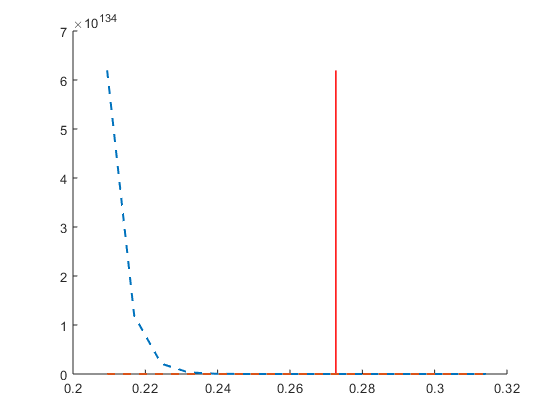

[struc,dt] = struc_select('barycenter',dt);


parameters = est_regr(dt,struc,'16','ls');

# Simulate the last day of data

Use all data to validate the system and describe the allertness during the collection periods

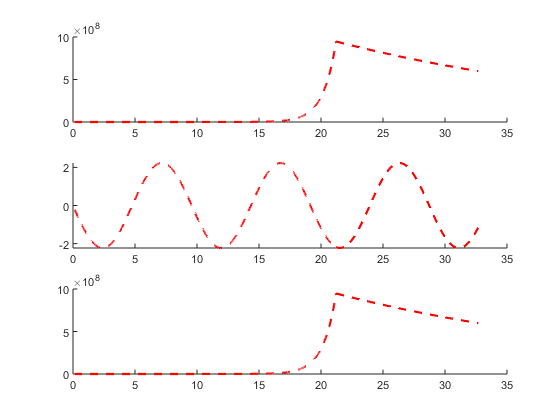

time_sam.init = [dt.t{1}(1), dt.init(2:end)];
time_sam.final = dt.final;
initial = dt.y{1}(1);

dts = sim_system(parameters,time_sam,initial);

figure(10);
for i = 1 : 1%length(dts.y)
    subplot(3,1,1); hold on;
    plot(dts.td{i},dts.yd{i},'r--','LineWidth',1.6);
    subplot(3,1,2); hold on;
    plot(dts.td{i},dts.yd{i} - dts.dhom{i},'r--','LineWidth',1.6);
    subplot(3,1,3); hold on;
    plot(dts.td{i},dts.dhom{i},'r--','LineWidth',1.6);
   
    if i ~= length(dts.y)
        subplot(3,1,1); hold on;
        plot(dts.tn{i},dts.yn{i},'r--','LineWidth',1.6);
        subplot(3,1,2); hold on;
        plot(dts.tn{i},dts.yn{i} - dts.nhom{i},'r--','LineWidth',1.6);
        subplot(3,1,3); hold on;
        plot(dts.tn{i},dts.nhom{i},'r--','LineWidth',1.6);    
    end
end